clc;
clear all;
close all;

## generate data

tfinal=200;
T_s=0.3

T_s = 0.3000

t = 0:T_s:tfinal;
u = zeros(numel(t),1);

#### General Input+white Noise

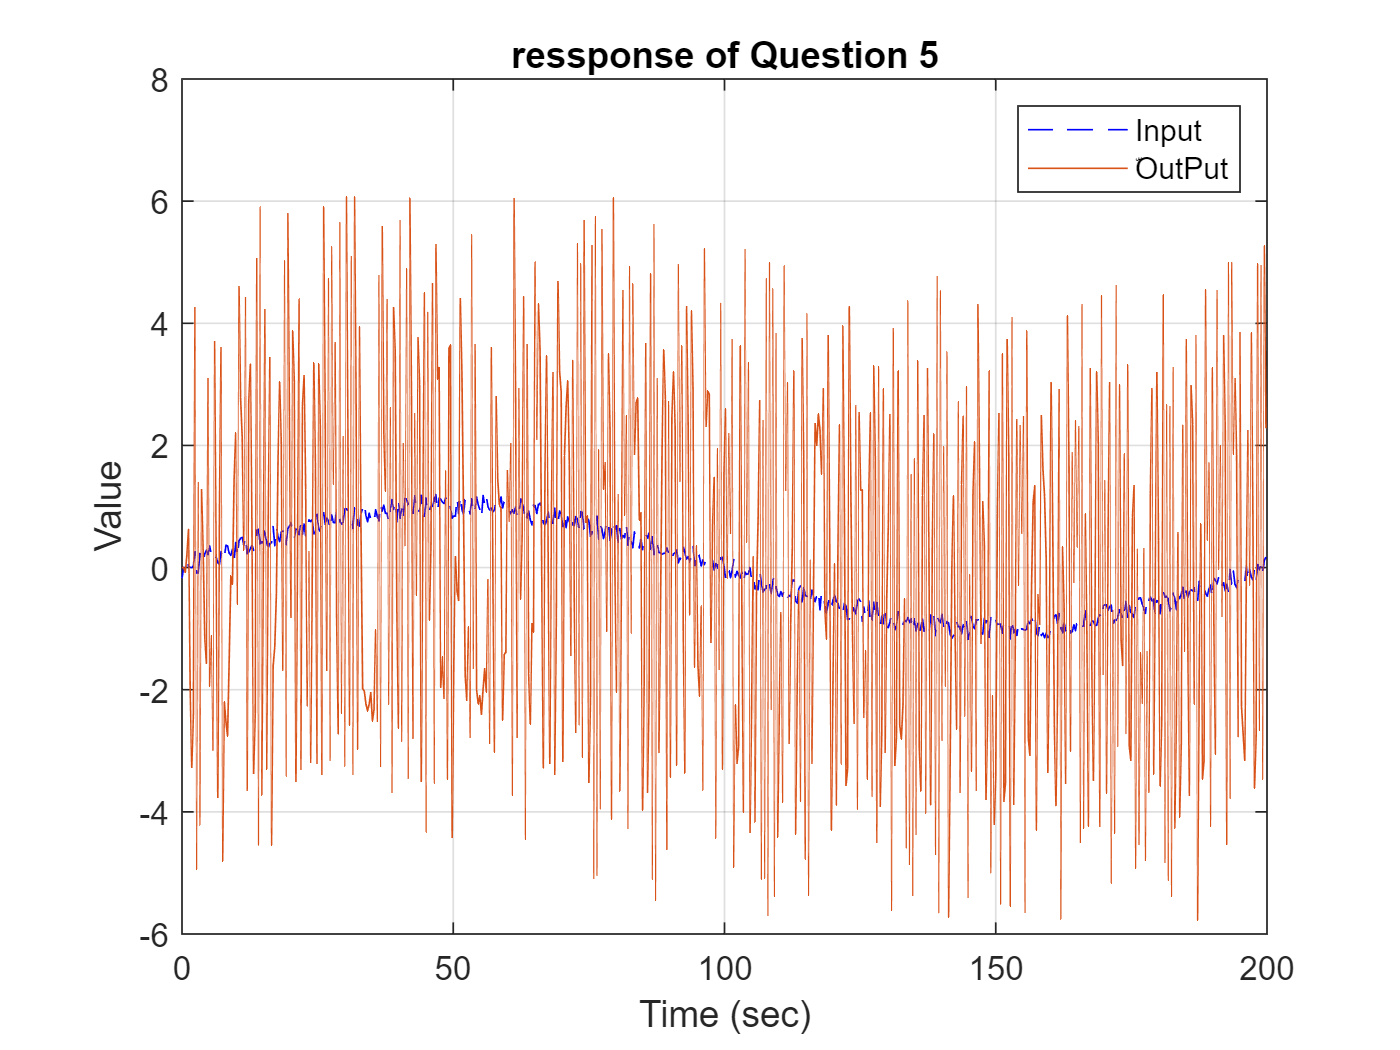

u = gensig('sine' , tfinal , tfinal ,T_s);
Noise=-0.2+(0.2+0.2)*rand(numel(t),1);
u=u+Noise;

y(1:numel(t),1)=zeros(numel(t),1);
for i=3:numel(t)
    y(i)=-4*sin(2.2*y(i-2))+-0.34*y(i-1)+u(i);
end
plot(t,u,'b--',t , y ,'LineWidth',0.5) ;
xlabel('Time (sec)') ;
ylabel('Value') ;
title('ressponse of Question 5') ;
grid on
legend('Input' , 'ّOutPut') ;

## Recursive Least Square estimation

AIC=[];

N = numel(y) ;
Trend=[]


Trend =

     []



for Degree=1:10:100
   %number of parameters
   Parameters_in_den=Degree*5;
   Parameters_in_num=Degree*5+1;
   Nv=Parameters_in_num+Parameters_in_den
  
    phi=[];
    Eror=zeros(1,N);

    theta(1:Nv,1:Nv) = zeros(Nv,Nv) ;
    P = 1e12*eye(Nv) ;
   for i = (max(Parameters_in_num,Parameters_in_den)+1):N
       phi(:,i) = [(y(i-1:-1:i-Parameters_in_den))' , (u(i-1:-1:i-Parameters_in_num))']';
       K = P*phi(:,i)*(1+phi(:,i)'*P*phi(:,i))^(-1) ;
       P = (eye(Nv) - K*phi(:,i)')*P ;
       theta(:,i) = theta(:,i-1) + K*(y(i) - phi(:,i)'*theta(:,i-1));  
   end
   AIC(Degree)=N*log(norm(y(1:i)-theta(1:i))+2*Nv);
   Trend(Nv)=AIC(end);
end

Nv = 11

Nv = 111

Nv = 211

Nv = 311

Nv = 411

Nv = 511

Nv = 611

Nv = 711

Nv = 811

Nv = 911

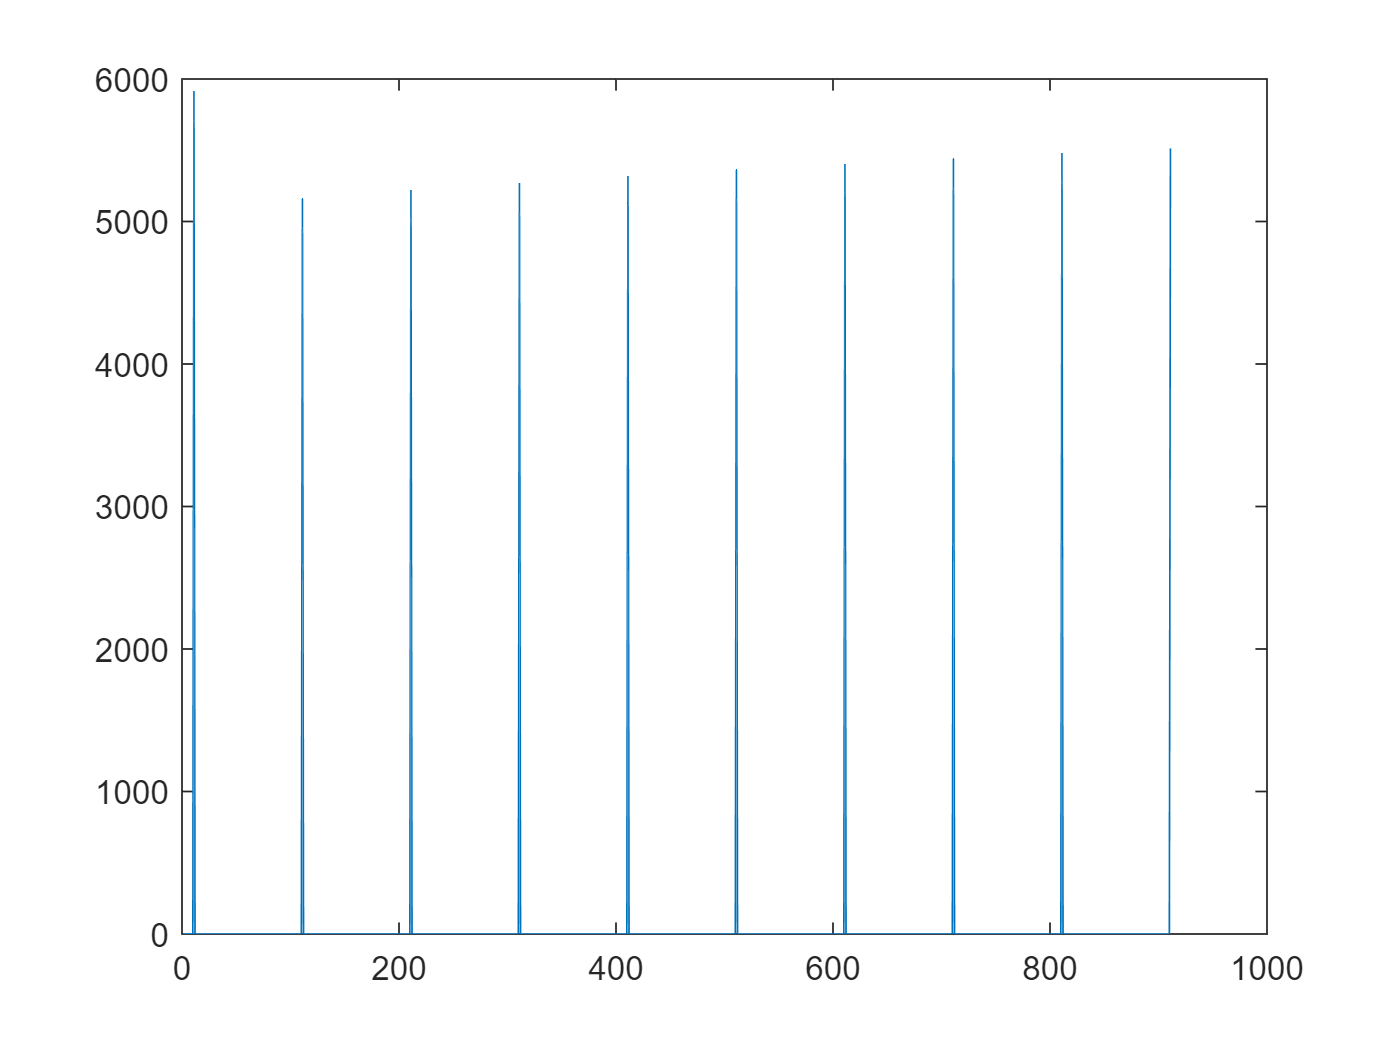


    plot(1:Nv, Trend)


% % % % figure;
% % % % hold on;
% % % % for k1=1:1:(Nv);
% % % %     subplot(ceil((Nv)/2),2,k1);
% % % %     plot(theta(k1,:));
% % % % end
% % % % hold off;